clear all
close all
clc

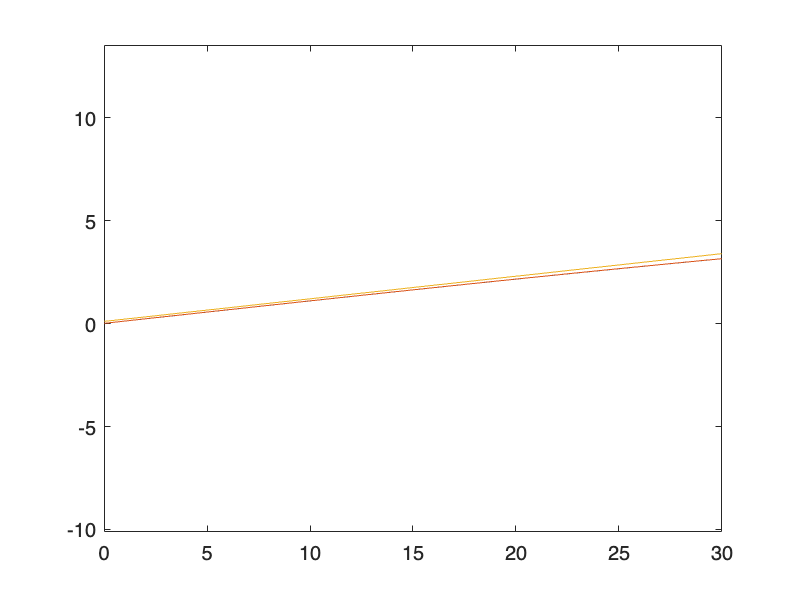

% Problem 1


for a=1:31

    [~,Cl,~,~,~,~,~,~] = computePanelData(10,-1000,a-1,10,1);
    Cl_vect10(a)=Cl;

    [~,Cl,~,~,~,~,~,~] = computePanelData(10,-1000,a-1,100,1);
    Cl_vect100(a)=Cl;

    Cl_vect_eqxn(a)= 2*pi*(a*(pi/180));

end

alpha = linspace(0,30,31);

Cl_vect_total = [Cl_vect10;Cl_vect100;Cl_vect_eqxn];

plot(alpha,Cl_vect_total);
axis equal

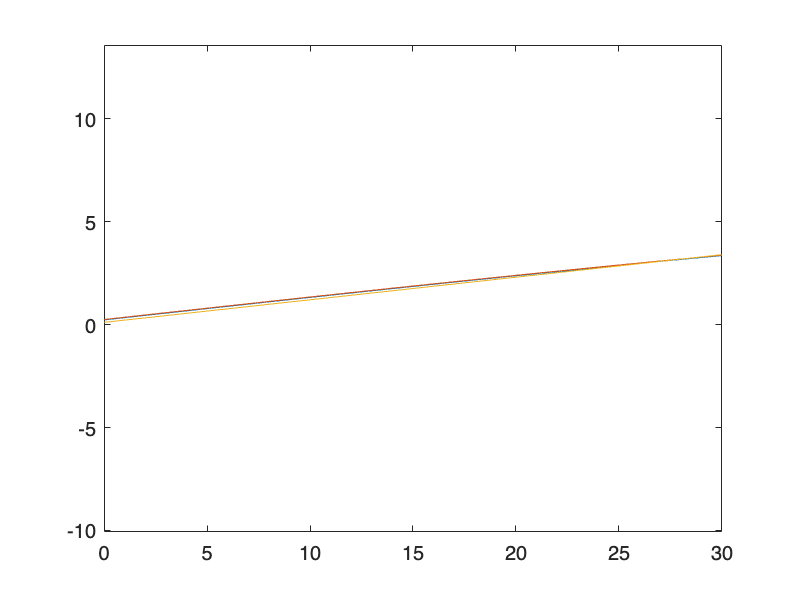

% Problem 2

for a=1:31

    [~,Cl,~,~,~,~,~,~] = computePanelData(10,-62,a-1,10,1);
    Cl_vect10_cam(a)=Cl;

    [~,Cl,~,~,~,~,~,~] = computePanelData(10,-62,a-1,100,1);
    Cl_vect100_cam(a)=Cl;

    Cl_vect_eqxn_cam(a)= 2*pi*(a*(pi/180));

end

alpha = linspace(0,30,31);

Cl_vect_total_cam = [Cl_vect10_cam;Cl_vect100_cam;Cl_vect_eqxn_cam];

plot(alpha,Cl_vect_total_cam);
axis equal

% Problem 5

N = 10

N = 10

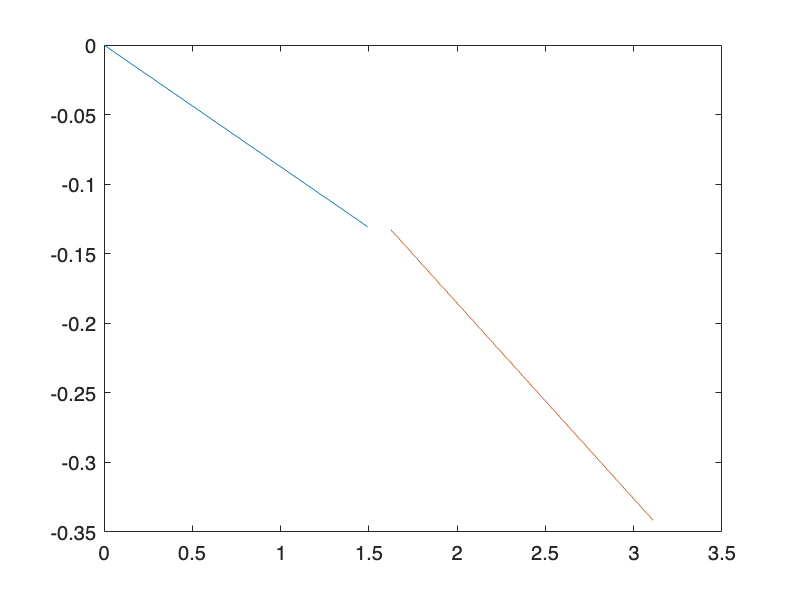


% Upstream airfoil
xi_u = 0;
yi_u = 0;
xf_u = 1.494;
yf_u = -0.1307;

% Downstream airfoil
xi_d = 1.624;
yi_d = -0.1327;
xf_d = 3.109;
yf_d = -0.3415;

%Length_u = sqrt((xf_u-xi_u)^2+(yf_u-yi_u)^2)
%Length_d = sqrt((xf_d-xi_d)^2+(yf_d-yi_d)^2)

% Points for the upstream airfoil
x_u = linspace(xi_u,xf_u,N+1);
y_u = linspace(yi_u,yf_u,N+1);
plot(x_u,y_u);

hold on

% Points for the downstream airfoil
x_d = linspace(xi_d,xf_d,N+1);
y_d = linspace(yi_d,yf_d,N+1);
plot(x_d,y_d);


% creating the panels
            
                PCoords_g = zeros(N,4); 
                PCoords_g_u = zeros(N,4); 
                PCoords_g_d = zeros(N,4); 


                for e=1:N
                        
                    PCoords_g_u(e, 1) = x_u(e);
                    PCoords_g_u(e, 2) = y_u(e);
                    PCoords_g_u(e, 3) = x_u(e+1);
                    PCoords_g_u(e, 4) = y_u(e+1);

                end


                for e=1:N
                        
                    PCoords_g_d(e, 1) = x_d(e);
                    PCoords_g_d(e, 2) = y_d(e);
                    PCoords_g_d(e, 3) = x_d(e+1);
                    PCoords_g_d(e, 4) = y_d(e+1);

                end
                
                PCoords_g =[PCoords_g_u; PCoords_g_d];


% panel length

                L = 1.5/N;

% calculate the normal and tangential vectors

% x_g = zeros(N,2);
%                 for e=1:N
%                     x_g(e,1) = (PCoords_g(e,3)-PCoords_g(e,1))/L(e); %i_hat
%                     x_g(e,2) = (PCoords_g(e,4)-PCoords_g(e,2))/L(e); %j_hat
%                 end
% 
%                 y_g = zeros(N,2);
%                 y_g = [0 1; -1 0]*transpose(x_g);
%                 y_g = -transpose(y_g);



